%load spectralCoherence_results_20190423

freqRange = [13 30];
freq = cohDat(1).freq;
cohmat = [];
freqIndx = find((freq > freqRange(1) ) & (freq < freqRange(2)));
cohmat(1:211,1:211) = squeeze(mean(cohDat(1).coh(:,:,freqIndx),3));
cohmat(212:243,212:243) = squeeze(mean(cohDat(2).coh(:,:,freqIndx),3));
cohmat(1:211,212:243) = squeeze(mean(cohDat(3).coh(:,:,freqIndx),3))';


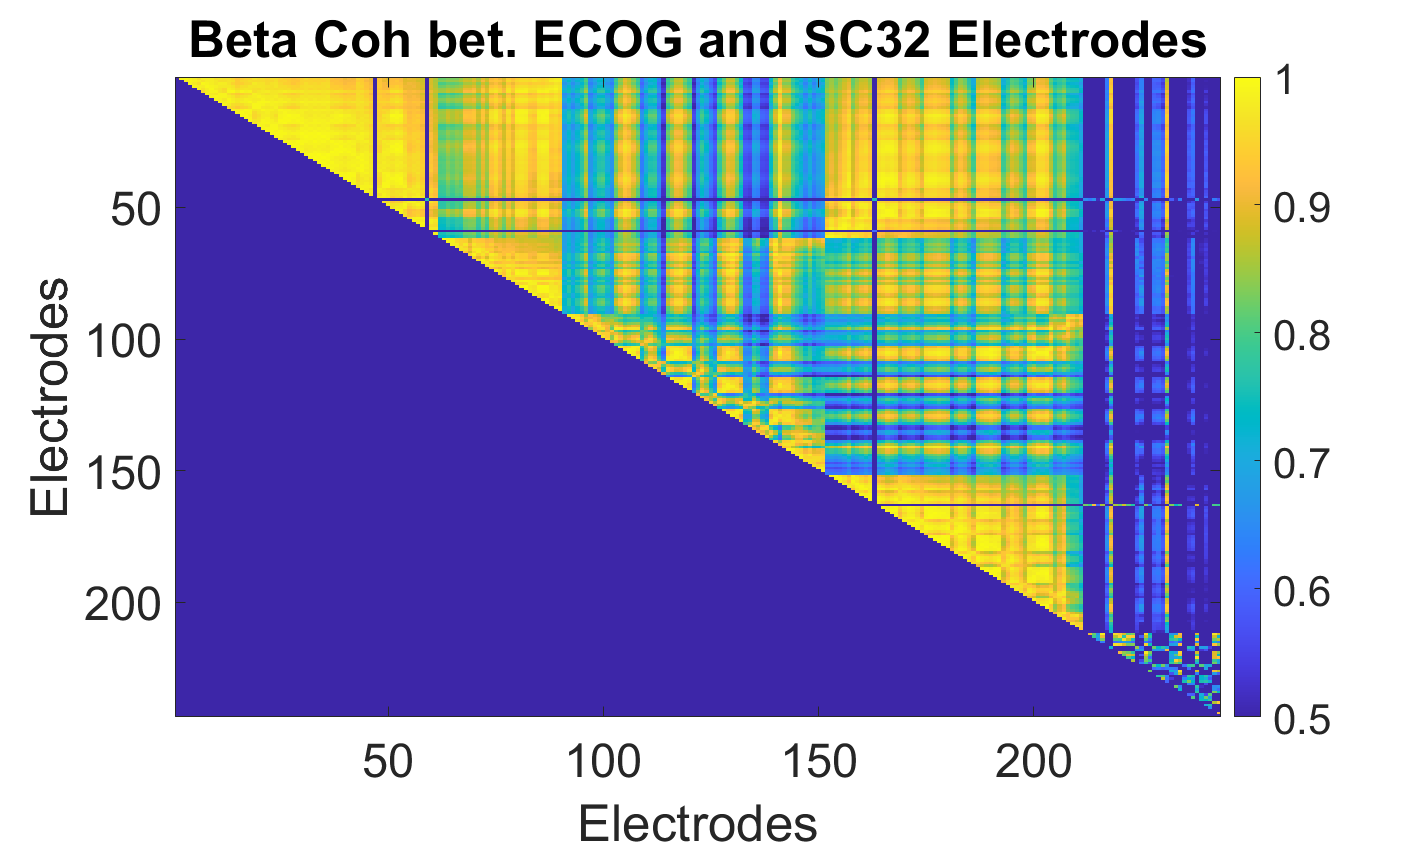

figure('units','normalized','outerposition',[0 0 0.75 0.75])
imagesc(cohmat)
xlabel('Electrodes')
ylabel('Electrodes')
colorbar
colorbar
caxis([0.5 1])
set(gca,'fontSize',28)
title('Beta Coh bet. ECOG and SC32 Electrodes')
print(gcf, 'centerout_matrix.jpg', '-djpeg', '-r600');